# Practice Problems - Writing Data Analysis Programs with Matlab

## Problem 1: Importing Data and Table Manipulation

#### Links and References for this Example

Covid-19 data

[https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

Epidemiological modelling code using Matlab - Matlab central

[https://uk.mathworks.com/matlabcentral/fileexchange/74545-generalized-seir-epidemic-model-fitting-and-computation?s_tid=LandingPageTabfx](https://uk.mathworks.com/matlabcentral/fileexchange/74545-generalized-seir-epidemic-model-fitting-and-computation?s_tid=LandingPageTabfx)

Epidemiological modelling code using Matlab - github repository

[https://github.com/ECheynet/SEIR](https://github.com/ECheynet/SEIR)

### Part 1.1 Extract and Transform the Data

In this part of the problem we will download the data from a remote repository we will transform the data into a form which we can use for investigation and analysis.

**1.1.1 Use the websave function to down load a csv file containing the number of confirmed global infections.**

Hint:

url=['https://raw.githubusercontent.com/CSSEGISandData/COVID-19/master/csse_covid_19_data/csse_covid_19_time_series/time_series_covid19_',status{ii},'_global.csv'];

outfilename = websave(filename,url)

status = {'confirmed','deaths','recovered'};

To determine the correct link for the file you need to download visit the site:

[https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

Open the selected file in git e.g. 

[https://github.com/CSSEGISandData/COVID-19/blob/master/csse_covid_19_data/csse_covid_19_time_series/time_series_covid19_confirmed_global.csv](https://github.com/CSSEGISandData/COVID-19/blob/master/csse_covid_19_data/csse_covid_19_time_series/time_series_covid19_confirmed_global.csv)

To determine the correct download for the csv datafile click the link on the git hub page which is labelled Raw.

status = {'confirmed','deaths','recovered'};
url = ['https://raw.githubusercontent.com/CSSEGISandData/COVID-19/master/csse_covid_19_data/csse_covid_19_time_series/time_series_covid19_',status{ii},'_global.csv'];
filename="myout.csv"; % to store the read data

outfilename = websave(filename,url)

outfilename = '/Users/mikegriffiths/proj/matlab-datsci-intro/livescript/myout.csv'

### Part 1.2 Data Transformation, Loading, Wrangling and Visualisation

**1.2.1 Use the readtable function to load the data set covid.csv**

clf
%T = readtable('headersAndMissing.txt','Format','auto')
datac=readtable('../data/covid.csv','Format','auto')

datac = 502×66 table
            Var1                      Var2                  Var3            Var4            Var5           Var6           Var7           Var8           Var9           Var10          Var11          Var12          Var13          Var14         Var15         Var16         Var17         Var18         Var19         Var20         Var21         Var22         Var23          Var24          Var25          Var26          Var27          Var28          Var29          Var30      

**1.2.2 Use the find and contains command to construct a command which will extract the confirmed infections for China (Hubei), UK, Italy, France, Spain and Germany.**

**Hints: Use help to find out how to use the find and contains command. You will also need to make use of the matlab commands table2cell, str2num, datestr and cellfun. The call to cellfun will need to use the handle to str2num or datestr e.g. @datestr, @str2num. When we plot the graphs in the next exercise we will use the date field which is the first row of the table.**

indLocation = find(contains(datac.Var1,'Hebei')==1)

indLocation = 175

chebei=table2cell(datac(175,5:end));
datesc=table2cell(datac(1,5:end));

dates=cellfun(@datestr,datesc,'UniformOutput',false)

dates = 1×62 cell array
    {'22-Jan-2020'}    {'23-Jan-2020'}    {'24-Jan-2020'}    {'25-Jan-2020'}    {'26-Jan-2020'}    {'27-Jan-2020'}    {'28-Jan-2020'}    {'29-Jan-2020'}    {'30-Jan-2020'}    {'31-Jan-2020'}    {'01-Feb-2020'}    {'02-Feb-2020'}    {'03-Feb-2020'}    {'04-Feb-2020'}    {'05-Feb-2020'}    {'06-Feb-2020'}    {'07-Feb-2020'}    {'08-Feb-2020'}    {'09-Feb-2020'}    {'10-Feb-2020'}    {'11-Feb-2020'}    {'12-Feb-2020'}    {'13-Feb-2020'}    {'14-Feb-2020'}    {'15-Feb-2020'}    {'16-Feb-2020'}    {'17-Feb-2020'}    {'18-Feb-2020'}    {'19-Feb-2020'}    {'20-Feb-2020'}    {'21-Feb-2020'}    {'22-Feb-2020'}    {'23-Feb-2020'}    {'24-Feb-2020'}    {'25-Feb-2020'}    {'26-Feb-2020'}    {'27-Feb-2020'}    {'28-Feb-2020'}    {'29-Feb-2020'}    {'01-Mar-2020'}    {'02-Mar-2020'}    {'03-Mar-2020'}    {'04-Mar-2020'}    {'05-Mar-2020'}    {'06-Mar-2020'}    {'07-Mar-2020'}    {'08-Mar-2020'}    {'09-Mar-2020'}    {'10-Mar-2020'}    {'11-Mar-2020'}    {'12-Mar-2020'}    {'1

hebei=cellfun(@str2num,chebei)

hebei =      0     0     0     0     0     0     0     0     0     0     0     3     3     4     6    13    22    30    34    41    48    54    68    87   101   105   122   136   152   169   184   203   219   234   248   261   274   277   282   294   296   300   301   304   305   307   307   307   307   307



uk=cellfun(@str2num,table2cell(datac(find(contains(datac.Var2,'United Kingdom')==1),5:end)));
italy=cellfun(@str2num,table2cell(datac(find(contains(datac.Var2,'Italy')==1),5:end)));
newyork=cellfun(@str2num,table2cell(datac(101,5:end)));

**1.2.2 Use plots to compare the number of confirmed cases for different countries**

Hint: Use logarithmic plots and compare the time evolution of the number of confirmed cases.


covplot=plot(hebei)

covplot =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62]
              YData: [0 0 0 0 0 0 0 0 0 0 0 3 3 4 6 13 22 30 34 41 48 54 68 87 101 105 122 136 152 169 184 203 219 234 248 261 274 277 282 294 296 300 301 304 305 307 307 307 307 307 308 310 310 310 310 310 310 310 310 310 310 310]
              ZData: [1×0 double]

  Show all properties


hold on
plot(uk(3,:))

ax=gca;
ax.XTickLabel=datesc

ax =   Axes with properties:

             XLim: [0 70]
             YLim: [0 350]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



xlabel('Date')
ylabel('Infected')


indLocation = find(contains(datac.Var1,'Hubei')==1)

indLocation = 156

clf
iFrance=find(contains(datac.Var2,'France')==1 & contains(datac.Var1,'France')==1)

iFrance = 159

iItaly=find(contains(datac.Var2,'Italy')==1)

iItaly = 18

iGermany=find(contains(datac.Var2,'Germany')==1)

iGermany = 13

iSpain=find(contains(datac.Var2,'Spain')==1)

iSpain = 20


plot(log10(cellfun(@str2num,table2cell(datac(iFrance,5:end)))))
hold on
%plot(log10(cellfun(@str2num,table2cell(datac(iItaly,5:end)))))
plot(log10(cellfun(@str2num,table2cell(datac(iGermany,5:end)))))
plot(log10(cellfun(@str2num,table2cell(datac(iSpain,5:end)))))
plot(log10(uk(3,:)))
ax=gca;
ax.XTickLabel=datesc

ax =   Axes with properties:

             XLim: [20 70]
             YLim: [0 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



xlabel('Date')
ylabel('Infected')

## Problem2: Regression Analysis

**For this problem we will study the motor vehicle data and use this data to investigate the relationship between engine capacity and fuel consumption.**

**2.1.1 Use the readtable function to load the csv datafile mtcars.csv in the data folder. Plot a 2x2 subplot array illustrating the relationship between mpg and the properties cyl, disp, wt and hp.**

data=readtable('../data/mtcars.csv')

data = 32×12 table
             Var1              mpg     cyl    disp     hp     drat     wt      qsec     vs    am    gear    carb
    _______________________    ____    ___    _____    ___    ____    _____    _____    __    __    ____    ____

    {'Mazda RX4'          }      21     6       160    110     3.9     2.62    16.46    0     1      4       4  
    {'Mazda RX4 Wag'      }      21     6       160    110     3.9    2.875    17.02    0     1      4       4  
    {'Datsun 710'         }    22.8     4       108     93    3.85     2.32    18.61    1     1      4       1  
    {'H

subplot(2,2,1);
scatter(data.cyl,data.mpg);
xlabel('Cylinders');
ylabel('Fuel Consumption (Miles per Gallon)');

subplot(2,2,2);
scatter(data.disp,data.mpg);
xlabel('Capacity');
ylabel('Fuel Consumption (Miles per Gallon)');

subplot(2,2,3);
scatter(data.disp,data.mpg);
xlabel('Weight');
ylabel('Fuel Consumption (Miles per Gallon)');

subplot(2,2,4);
scatter(data.hp,data.mpg);
xlabel('Power (hp)');
ylabel('Fuel Consumption (Miles per Gallon)');

**2.1.2 Experiment with mean median and mode which variables exhibit the greatest difference between these values? Plot histograms to investigate these values.**

st=cell(3,3);
st{1,1}=mean(data.hp); st{1,2}=median(data.hp); st{1,3}=mode(data.hp);
st{2,1}=mean(data.mpg); st{2,2}=median(data.mpg); st{2,3}=mode(data.mpg);
st{3,1}=mean(data.disp); st{3,2}=median(data.disp); st{3,3}=mode(data.disp);

disp(st);

    {[146.6875]}    {[     123]}    {[     110]}
    {[ 20.0906]}    {[ 19.2000]}    {[ 10.4000]}
    {[230.7219]}    {[196.3000]}    {[275.8000]}



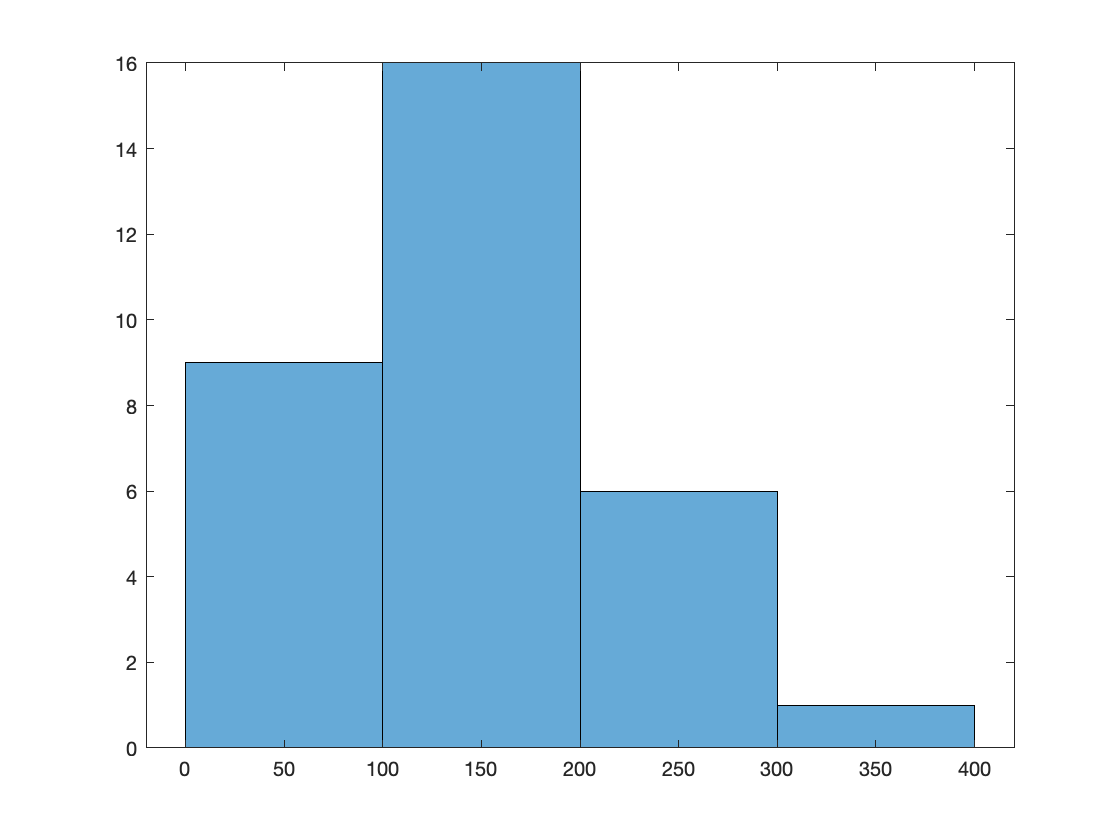


histogram(data.hp)

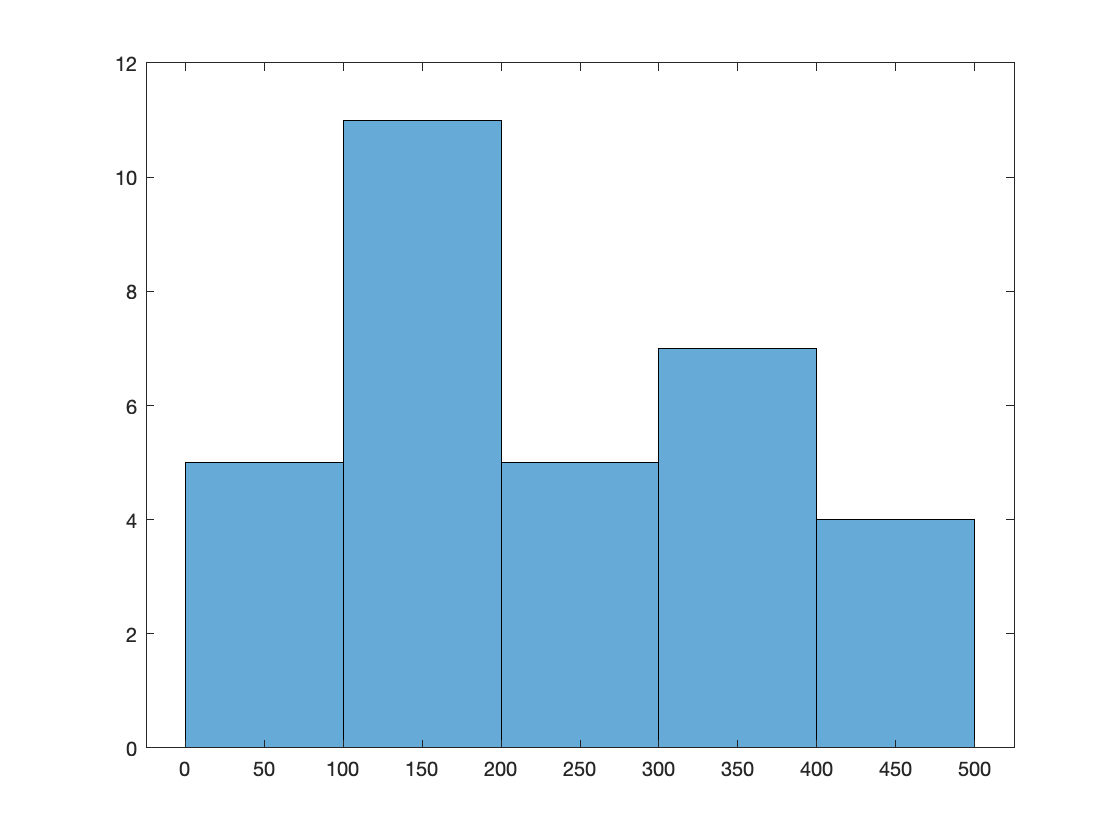

histogram(data.disp)

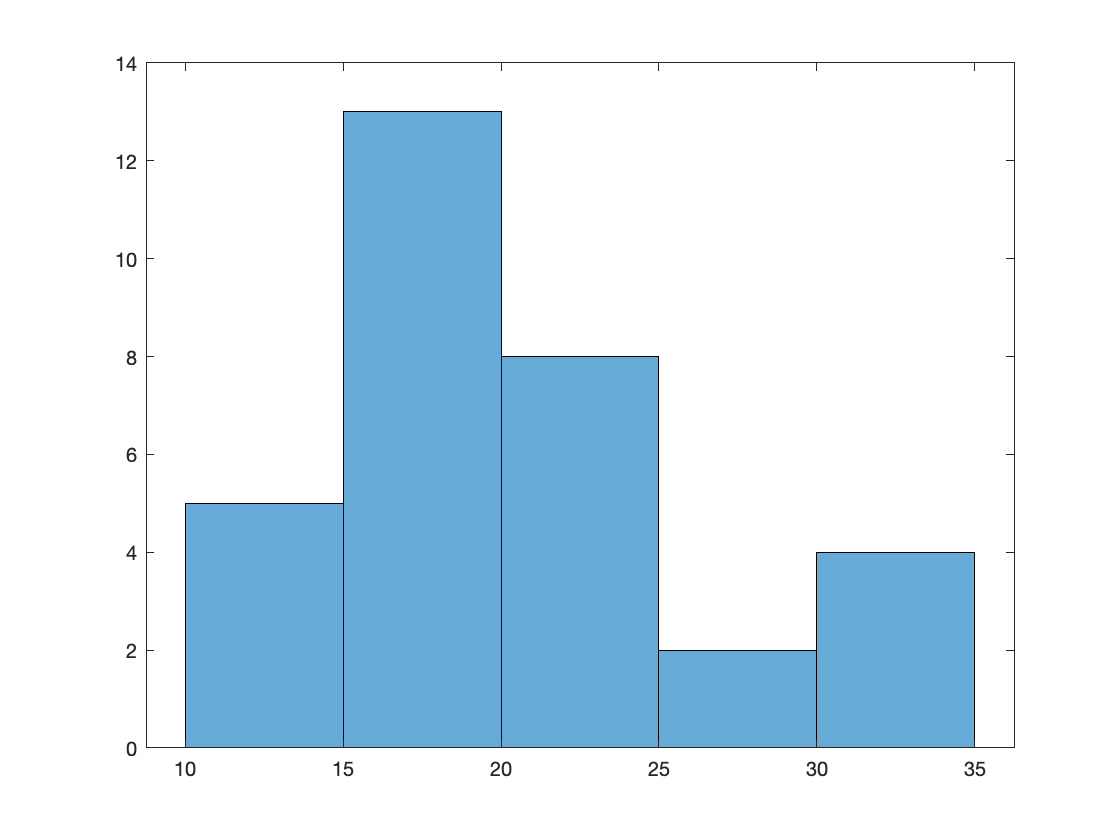

histogram(data.mpg)

**2.1.3 Use the fitdist function and the probability distribution function (pdf) to compare the histogram with the probability distribution function.**

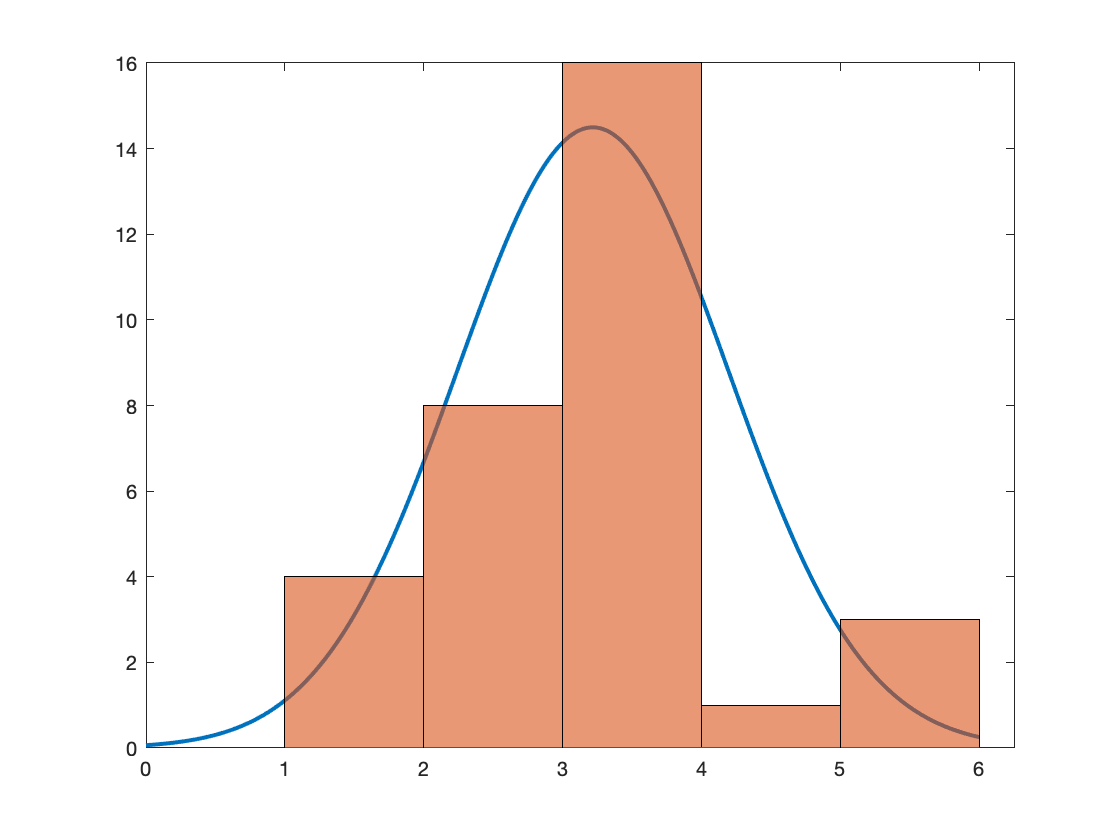


pdwt = fitdist(data.wt,'Normal');
pdhp = fitdist(data.hp,'Normal');
x_values = 0:0.01:6;
y = 16*pdf(pdwt,x_values)/0.45;
plot(x_values,y,'LineWidth',2)
hold on
histogram(data.wt)

hold off

pdwt = fitdist(data.wt,'Normal')
x_values = 0:2:400;

y = 16000*pdf(pdhp,x_values)/6;
plot(x_values,y,'LineWidth',2)
hold on
histogram(data.hp)
hold off

**2.1.4 Use the least squareas method   and the fitlm function to compute the best fit for the engine horse power and the fuel consumption (data.mpg). Compare the results with a plot.**

**Hint: For the Least squares method use the notes, you can also use the following web page**

[http://mathworld.wolfram.com/LeastSquaresFitting.html](http://mathworld.wolfram.com/LeastSquaresFitting.html)

xv=data.hp

xv =    110
   110
    93
   110
   175
   105
   245
    62
    95
   123


yv=data.mpg

yv =    21.0000
   21.0000
   22.8000
   21.4000
   18.7000
   18.1000
   14.3000
   24.4000
   22.8000
   19.2000


num=numel(xv);
xmean=mean(xv);
ymean=mean(yv);
sxx=sum(xv.*xv);
syy=sum(yv.*yv);
sx=sum(xv);
sy=sum(yv);

ssxx=sum((xv-xmean).*(xv-xmean));
ssyy=sum((yv-ymean).*(yv-ymean));

ssxy=sum((xv-xmean).*(yv-ymean));
b=ssxy/ssxx;

a=ymean-b*xmean;

corcoeff=ssxy.^2/(ssxx*ssyy);

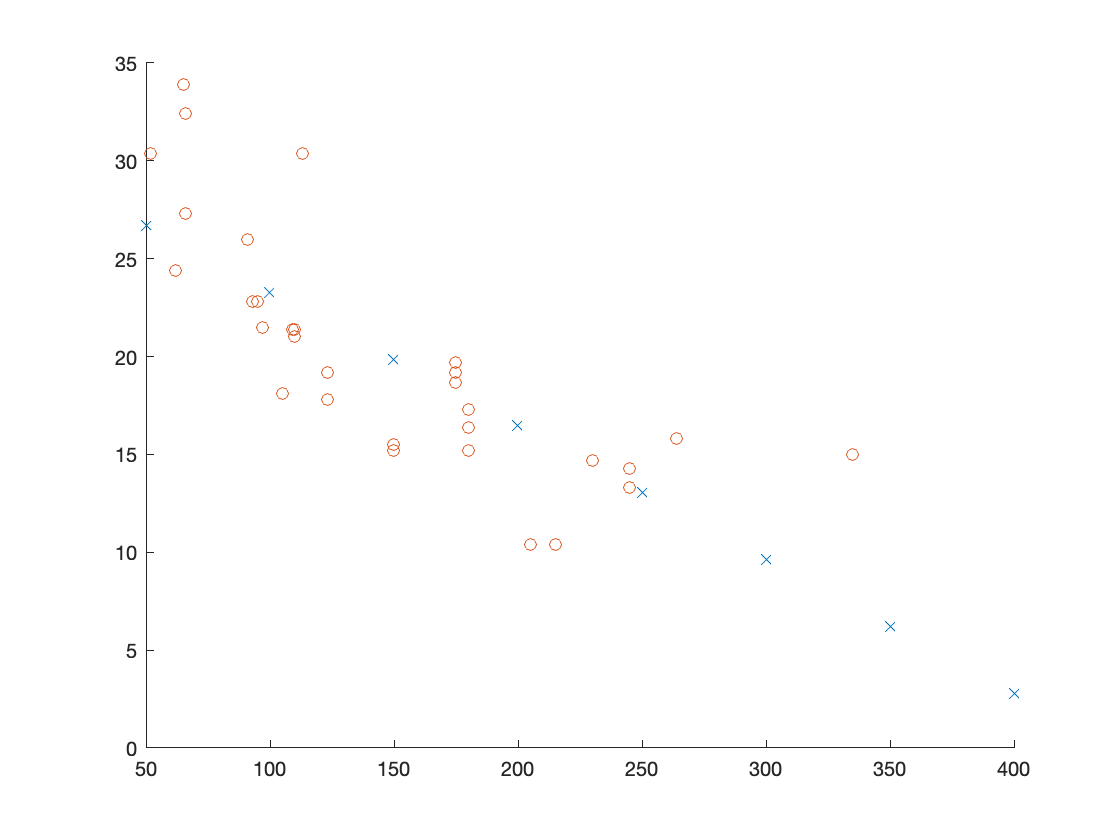

xtest=50:50:400;
ytest=b.*xtest+a;
figure
hold on
plot(xtest,ytest,'x');
plot(xv,yv,'o')
hold off

a

a = 30.0989

b

b = -0.0682

yv=data.mpg;
xv=data.hp;
tbl = table(xv,yv);
mdl = fitlm(tbl,'linear');

coeff=mdl.Coefficients.Estimate;
b=coeff(2);
a=coeff(1);



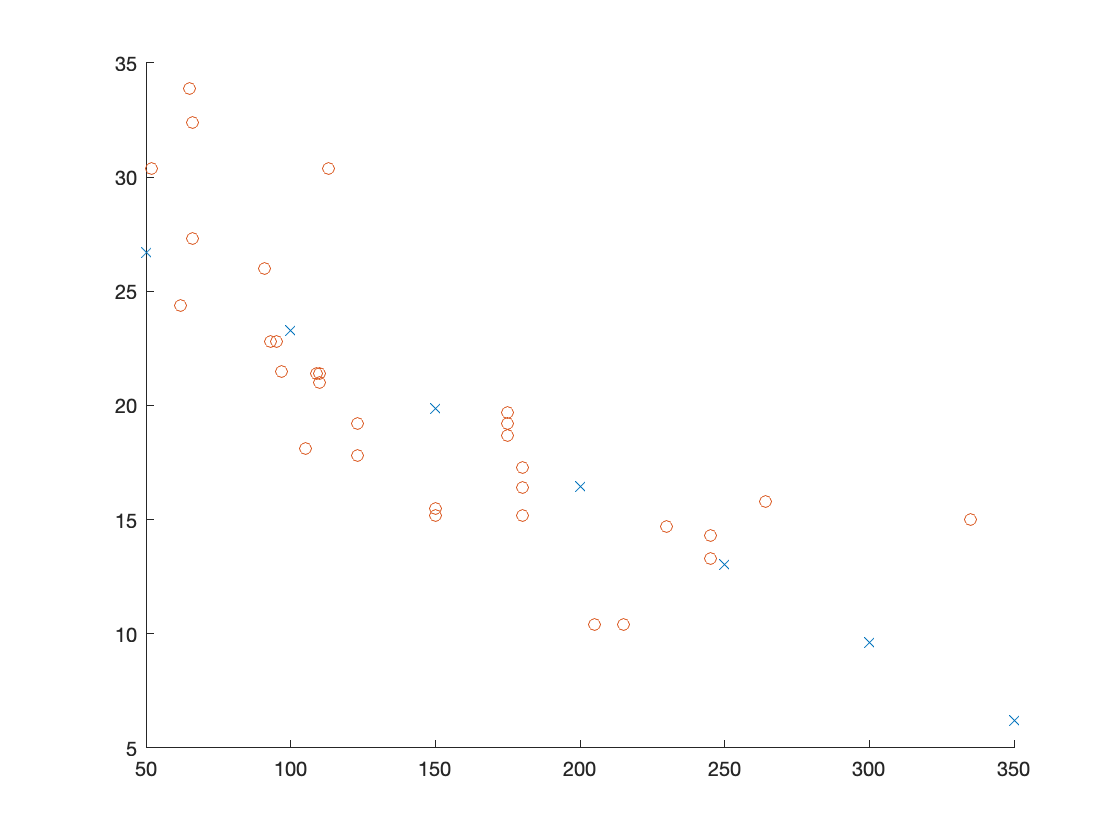

xtest=50:50:350;
ytest=b.*xtest+a;
figure
hold on
plot(xtest,ytest,'x');
plot(xv,yv,'o')
hold off


a

a = 30.0989

b

b = -0.0682